## State space model of a buck converter

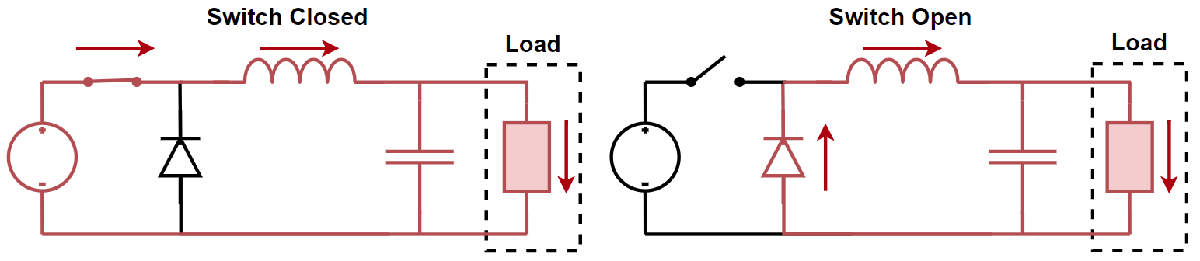

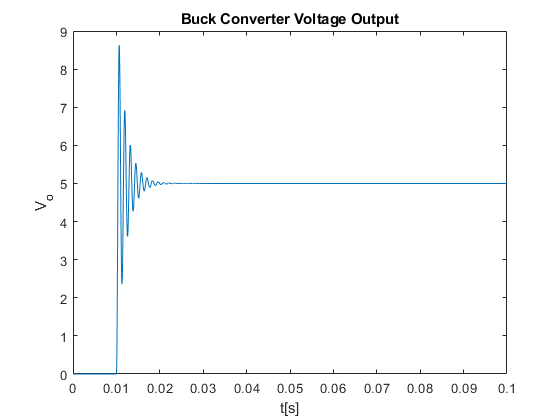


% % System variables ---------------------------------------------------------------
R = 100;        % Load Resistor
L = 4.1e-3;     % Inductor
C = 10e-6;      % Capacitor
V_i = 12;       % Input Voltage

% % Set the desired outputs --------------------------------------------------------
V_o = 5;        % Desired output voltage
duty = V_o/V_i; % Duty cycle calculation

% % State matrecies ----------------------------------------------------------------
A = [-1/(R*C), 1/C;
    -1/L,     0];

B = [0, V_i/L]';

C = [1, 0];

D = [];

% % System Simulation -------------------------------------------------------------
sys = ss(A, B, C, D);    % Create the system model

t = 0:0.1/10000:0.1;     % Setup the times series
u = zeros(length(t),1);  % Setup the input vector
u(t>0.01) = duty;        % Generate step input of the duty cycle after 0.01 seconds
x_0 = [0, 0]';           % Set initial conditions to zero

[y, t, x] = lsim(sys, u, t, x_0);

plot(t, y)
title("Buck Converter Voltage Output");
xlabel('t[s]')
ylabel('V_o')